clc 
clear all
close all

% N = input("Enter N\n")
N = 250

N = 250

t = (0:1:N-1)

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


% sysOrder = input("Give value of system order here. \n")
sysOrder = 13

sysOrder = 13

w0 = 0.05; 
d=sin(2*pi* t *w0);% desired signal
x=d + 0.1 *randn(size(t)); %input signal 



w = zeros (1,sysOrder) ; % Initially filter weights are zero

for n = sysOrder : N 
	u = x(n:-1:n-sysOrder+1) ;
    y(n)=  w * u'; % output of the adaptive filter
    e(n) = d(n) - y(n) ; % error signal = desired signal - adaptive filter output
    mu=0.8; 
    w = w + mu * u * e(n)  ; %filter weights update
end 

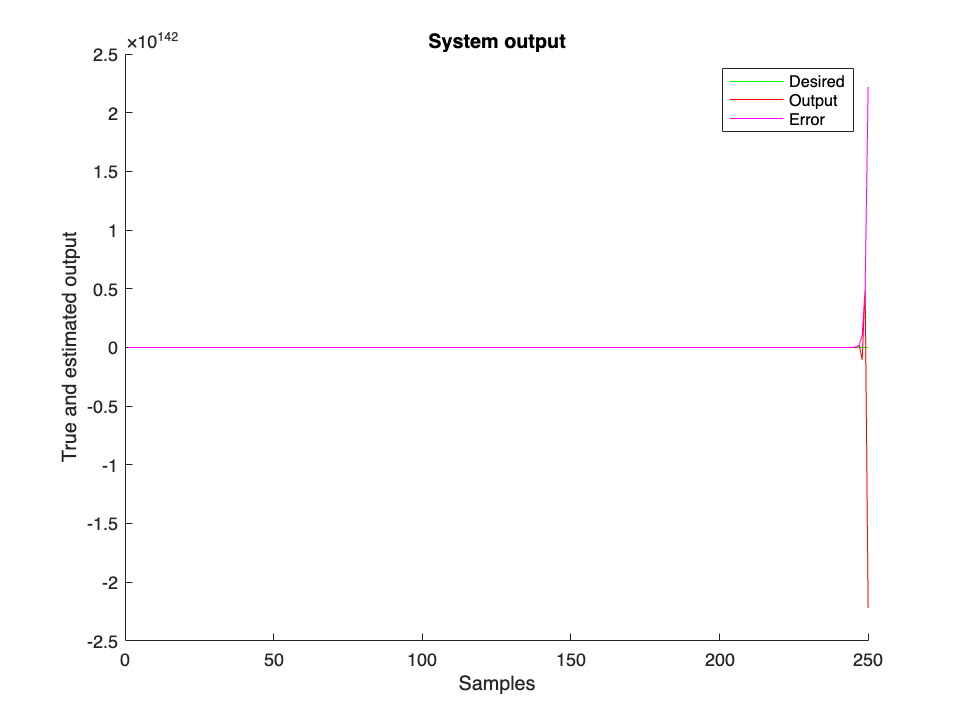

Error using axis>LocSetLimits (line 316)
Vector must have 4, 6, or 8 elements.

Error in axis (line 121)
                LocSetLimits(ax(j),cur_arg,names);


hold on
plot(d,'g')
plot(y,'r');
semilogy((abs(e)),'m') ;
title('System output') ;
xlabel('Samples')
ylabel('True and estimated output')
legend('Desired','Output','Error')
axis([0 N ])

figure
plot(b', 'k+')
hold on
plot(w, 'r*')
legend('Actual weights','Estimated weights')
title('Comparison of the actual weights and the estimated weights') ;
hold off